## **Connect and Sample Data from a Hokuyo URG-40LX Laser Scanner.mlx**

* CHECK OUT CLUDERDATA, POLYLINE*

*Code to drive a stepper motor connected to a stepper motor driver:*

*Arduino PWM pin 6 into R208 step input: yellow wire*

*Arduino pin 7  direction into the dir input(orange wire*

*Arduino 5v to 5v for optical insulator*

*Arduino ground to R208 logic ground(white wire not green wire)*

*Use built in LED pin 13 for blink*

*Sign your name here and give the creation date and revision number*

*Bennett and Zeno: 2/22/22*

disp("Program running...");  %Indicate lidar code starts okay

Program running...


%To avoid incesent error messages in Windows 10, we will temportarily
%disable error warnings
warning('off','all');        %Turn off Matlab warnings

%Lidar is contained in a Matlab serial object, we need to clean up any old
%lidar objects in the workspace to prevent conflicts when we create a new
%one. For Fun-Robo, don't worry about what an object is for now, just
%treat it like a big fancy function.
serialObjs = instrfind;      %Read instrument objects from memory to MATLAB workspace
if ~isempty(serialObjs)      %If there are old objects, close them
    fclose(serialObjs);      %close serial port attatched to old Lidar
    delete(serialObjs);      %delete old lidar objects
end

clc                          %clear command window
clear                        %clear MATLAB workspace

## **Specify which serial port (USB) you have the test bench Hokuyo Lidar plugged into**

comPort = serialportlist("available");
disp("comPort Identified:")

comPort Identified:


comPort

comPort = "COM11"

## **Connect to Hokuyo Lidar and set its serial communication parameters**

s = serial('port') creates a serial port object s associated with the serial port specified by 'port'. If 'port' does not exist, or if it is in use, you cannot connect the serial port object to the device. 

disp("Conneting to lidar and setting Lidar parameters.");

Conneting to lidar and setting Lidar parameters.


disp("Expect a short delay while setting...")

Expect a short delay while setting...


lidar = serial(comPort,'BaudRate', 115200);  %create a serial port for Lidar
set(lidar,'Timeout',2);                     %set communication link timeout
set(lidar,'InputBufferSize',20000);         %set data input buffer size
set(lidar,'Terminator','LF/CR');            %set data stream terminator for fprintf
                                            %and fscanf. A read operation
                                            %with fgetl, fgets, or fscanf
                                            %completes when the terminator
                                            %value is read
%write a set of Hokuyo parameters to Lidar to configure it
fopen(lidar);                   %connects the serial port object, the lidar
pause(0.3);                     %pauses to allow command to transmit
fprintf(lidar,'SCIP2.0');       %writes string cmd to the lidar
pause(0.3);                     %pause to allow cmd to the lidar
fscanf(lidar);                  %reads ASCII data from the device connected to lidar
fprintf(lidar,'VV');            %pause to allow data to be read
pause(0.3);
fscanf(lidar,'BM');
pause(0.3);
fscanf(lidar);
fprintf(lidar,'MD0044072500');  %dont worry about what commands are sent for now
pause(0.3);
fscanf(lidar);
clc
disp("Lidar Set");

Lidar Set


## Initialize Lidar display

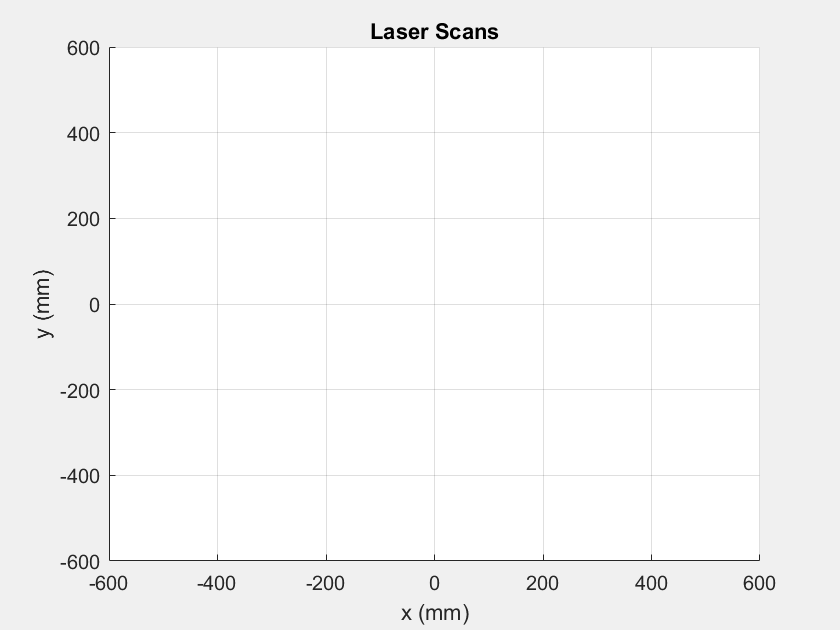

% stand alone figire window

LaserPlot1.figure = figure('Name', 'Hokuyu URG-04LX data', 'NumberTitle','off',...
    'MenuBar','figure','Units','normalized','Visible','on');
LaserPlot1.axis1 = axes('parent', LaserPlot1.figure, 'Units','normalized','NextPlot','replace');
grid(LaserPlot1.axis1, 'on')
LaserPlot1.axis1.Title.String = 'Laser Scans';
LaserPlot1.axis1.XLabel.String = 'X Axis';
LaserPlot1.axis1.YLabel.String = 'Y Axis';

laserRange = line('Parent', LaserPlot1.axis1, 'XData', [], 'YData', [], 'LineStyle', 'none', ...
    'marker', '.', 'color', 'b', 'LineWidth', 2);
grid on
axis([-600 600 -600 600])
xlabel('x (mm)')
ylabel('y (mm)')

## **Sample and Visualize Data**

read Lidar over USB, parse data, create plot of data in 60 sec max loop

**Dont pause and leave this code, needs to complete and then clean shutdown to avoid jamming com link to Lidar**

disp("Read and Plot Lidar Data, type and hold ctrl-c to stop")

Read and Plot Lidar Data, type and hold ctrl-c to stop


Blue


Green
Green
Green


Red


Blue
Blue
Blue


Red


Blue


Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green


Red


Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green
Green


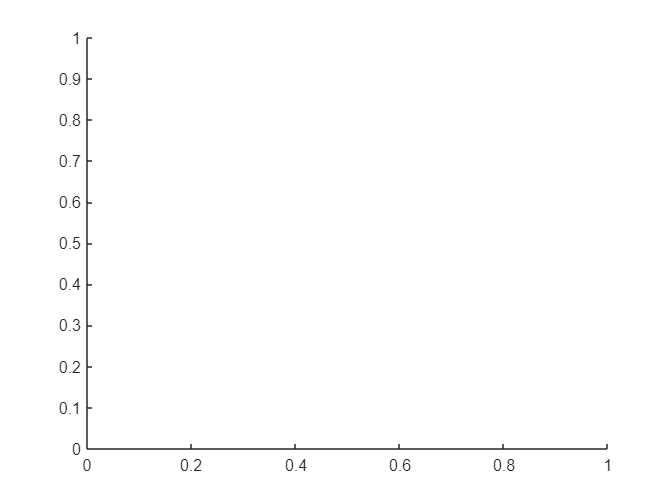

Index exceeds the number of array elements. Index must not exceed 0.


angles = (-120:240/682:120-240/682) * pi / 180; % Convert sensor steps to angles
tStart = tic;
iscan = 0;

while (iscan == 0)                              % countinuous loop

    

    [A] = FunRoboLidarScan(lidar);              % actual scan data
    data = filter(angles, A, 400);
    data2 = polCart(data);

    laserRange.XData = data2(1, :);          % Trig to find x-coord
    laserRange.YData = data2(2, :);          % Trig to find y-coord
    % update figures 


    [x1, y1, r, a] = circle_fit(data2(1,:), data2(2,:));

    viscircles([x1 y1], r);

    if(r < 38)
        disp("Green")
    elseif(r < 50)
        disp("Red")
    elseif(r < 80)
        disp('Blue');
    end

    drawnow

    pause(0.2)     % allow serial to keep up
    
    %Tigey what is this
    %Is this to delete the drawn circles?
    children = get(gca, 'children');
    delete(children(1));
    tElapsed = toc(tStart);                     % measure time since experiment start
    if (tElapsed > 60)                          % if gone too long, stop loop
        iscan = 1;
    end
end

## Disconnect Lidar

Please always run this section so the lidar doesnt become sentient 

fprintf(lidar, 'QT');
fclose(lidar);
clear lidar;
warning('on');
disp("the lidar has successfully been terminated")

## Functions

function [filtered] = filter(angles, A, cutoffDist)
    % A in mm, angles in rad
    A(A > cutoffDist) = 0;
    A(A < 40) = 0;
    
    filtered = [angles; A];
end

function data = polCart(polData)
    X = polData(2, :).*cos(polData(1, :));          % Trig to find x-coord
    Y = polData(2, :).*sin(polData(1, :)); 
    data = [X; Y];
    data( :, all(~data,1) ) = [];
end

function [rangescan]=FunRoboLidarScan(lidar)
proceed=0;
fprintf(lidar,'GD0044072500');
while (proceed==0)
    
if lidar.BytesAvailable >= 2134
    data = fscanf(lidar,'%c',2134);
    proceed = 1;
end

% data=fscanf(lidar);
% if numel(data)==2134
%     proceed=1;
% end

end

i = find(data == data(13));
rangedata=data(i(3)+1:end-1);
for j=0:31
onlyrangedata((64*j)+1:(64*j)+64)=rangedata(1+(66*j):64+(66*j));
end
j=0;
for i=1:floor(numel(onlyrangedata)/3)
encodeddist(i,:)=[onlyrangedata((3*j)+1) onlyrangedata((3*j)+2) onlyrangedata((3*j)+3)];
j=j+1;
end
for k=1:size(encodeddist,1)
    rangescan(k)=decodeSCIP(encodeddist(k,:));
end

end

% Function to decode range information transmitted using SCIP2.0 protocol.
% Works for only two and three bit encoding.
% Author- Shikhar Shrestha, IIT Bhubaneswar

function rangeval=decodeSCIP(rangeenc)
% Check for 2 or 3 Character Encoding
if rangeenc(1)=='0' && rangeenc(2)=='0' && rangeenc(3)=='0'
    rangeval=0;
    return;
end
if rangeenc(1)=='0'
    dig1=((rangeenc(2)-'!')+33);
    dig2=((rangeenc(3)-'!')+33);
    dig1sub=dig1-48;
    dig2sub=dig2-48;
    dig1bin=dec2bin(dig1sub,6);
    dig2bin=dec2bin(dig2sub,6);
    rangeval=bin2dec([dig1bin dig2bin]);
    return;
else
    dig1=((rangeenc(1)-'!')+33);
    dig2=((rangeenc(2)-'!')+33);
    dig3=((rangeenc(3)-'!')+33);
    dig1sub=dig1-48;
    dig2sub=dig2-48;
    dig3sub=dig3-48;
    dig1bin=dec2bin(dig1sub,6);
    dig2bin=dec2bin(dig2sub,6);
    dig3bin=dec2bin(dig3sub,6);
    rangeval=bin2dec([dig1bin dig2bin dig3bin]);
    return;
    
end
    
end

function [xo, yo, R, A] = circle_fit(x,y)
% Arguments:
% x:         x coordinates
% y:         y coordinates
%
% Output:
% xo:        circle x coordinate center
% yo:        circle y coordinate center
% R:         circle radius
x = x(:);
y = y(:);
% Fitting a circle to the data - least squares style. 
%Here we start with
% (x-xo).^2 + (y-yo).^2 = R.^2
% Rewrite:
% x.^2 -2 x xo + xo^2 + y.^2 -2 y yo + yo.^2 = R.^2
% Put in matrix form:
% [-2x -2y 1 ] [xo yo -R^2+xo^2+yo^2]' = -(x.^2 + y.^2)
% Solve in least squares way...
A = [-2*x -2*y ones(length(x),1)];
x = A\-(x.^2+y.^2);
xo=x(1);
yo=x(2);
R = sqrt(  xo.^2 + yo.^2  - x(3));
end
